# Introduction to System Modeling with MATLAB and Simulink, and the Use of the Live Editor 

In this course on system modeling with MATLAB and Simulink, you'll learn the basics of Simulink and Simscape, two powerful tools for simulating dynamic systems. We'll cover everything from connecting blocks to modeling complex mechanical systems, giving you practical experience in system analysis. Let's dive in and explore together!

## Simulink Basics

### Intro

[**Simulink**](https://www.mathworks.com/products/simulink.html) is a block diagram environment for multidomain time simulation. It supports system-level design, simulation, automatic code generation, and continuous test and verification of embedded systems The aforementioned concepts are the basics of the Model-Based Design which systematically uses virtual models throughout your development process.

Simulink provides a graphical editor, customizable block libraries, and solvers for modeling and simulating dynamic systems. 

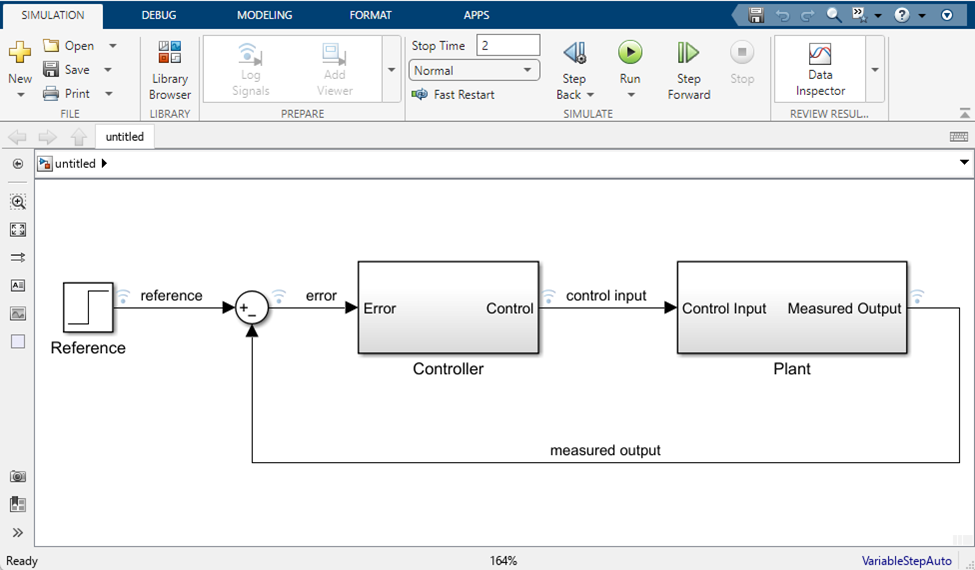

Simulink handles data in three categories:

- **Signals **— Block inputs and outputs, computed during simulation

- **States** — Internal values, representing the dynamics of the block, computed during simulation

- **Parameters** — Values that affect the behavior of a block, controlled by the user

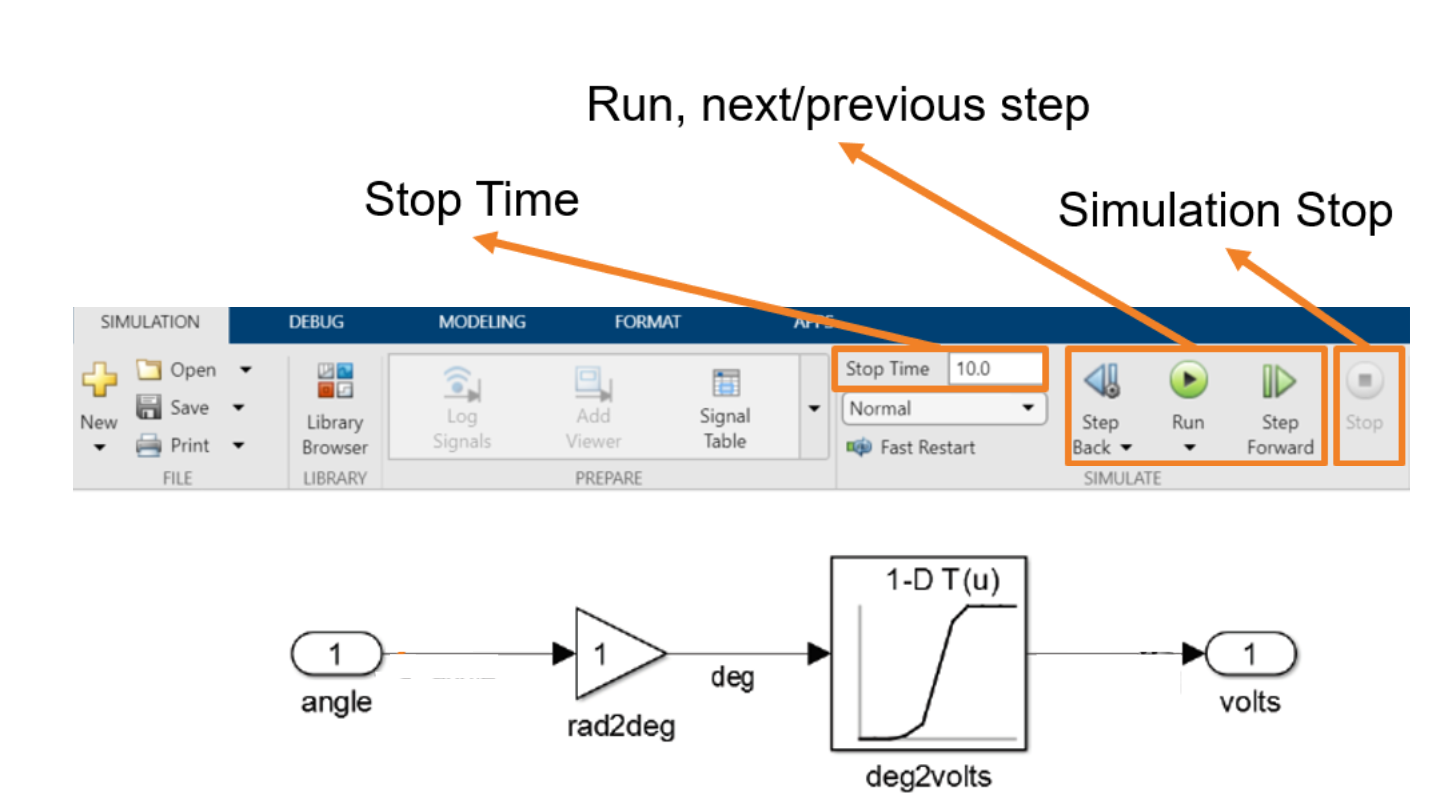

### Simulink and MATLAB

Simulink is integrated with MATLAB, enabling you to incorporate MATLAB algorithms into models and export simulation results to MATLAB for further analysis.

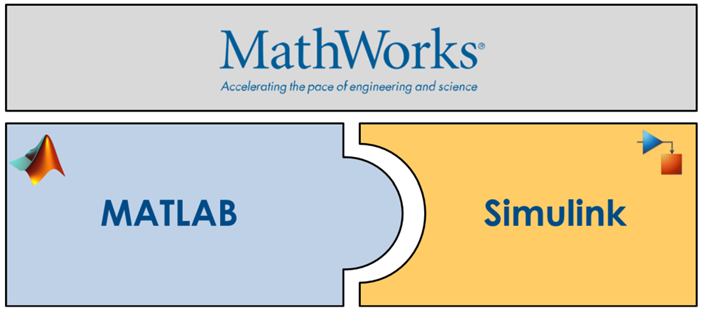

Simulink is built on top of MATLAB, it is one of the many tools (together with many Toolboxes) that are provided with MATLAB.

- **Simulink **makes simulations easier to achieve, by using blocks that correspond to codes you don't see. With Simulink, the model of the system you want to simulate is more readable, because it's represented by graphics.

- **MATLAB **is a high-level language for algorithm programming (even though today is something more articulated). With MATLAB you can implement line of codes to program your own routines or re-use those already provided (aka functions).

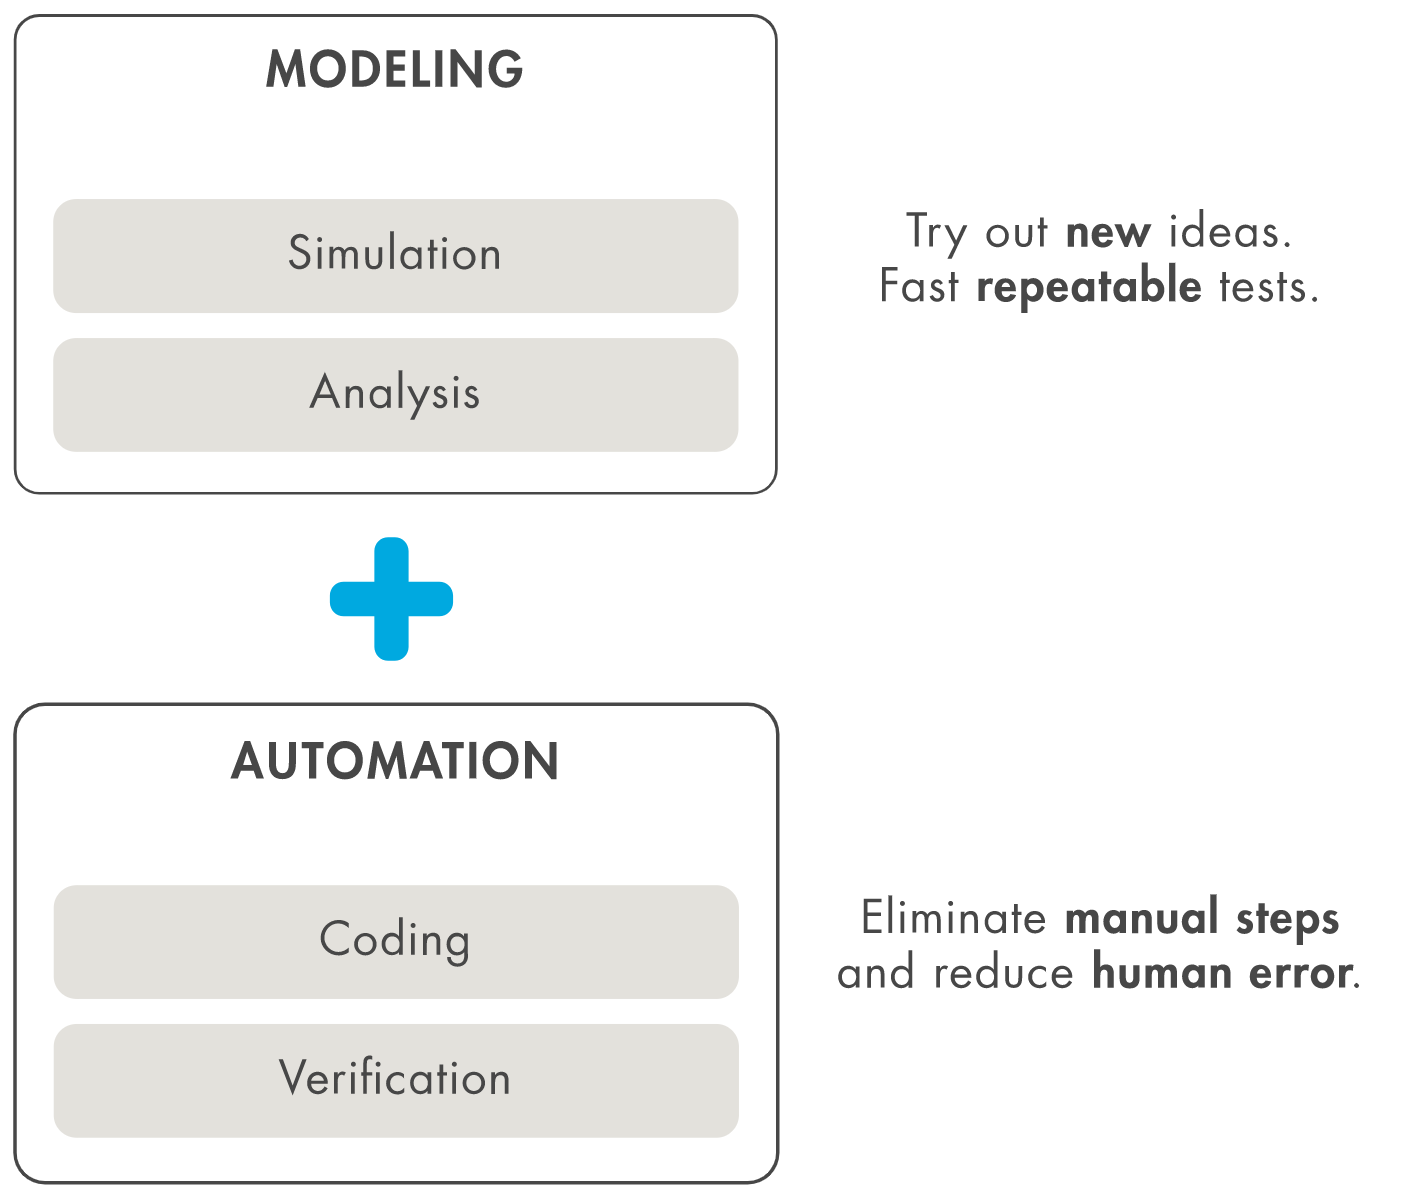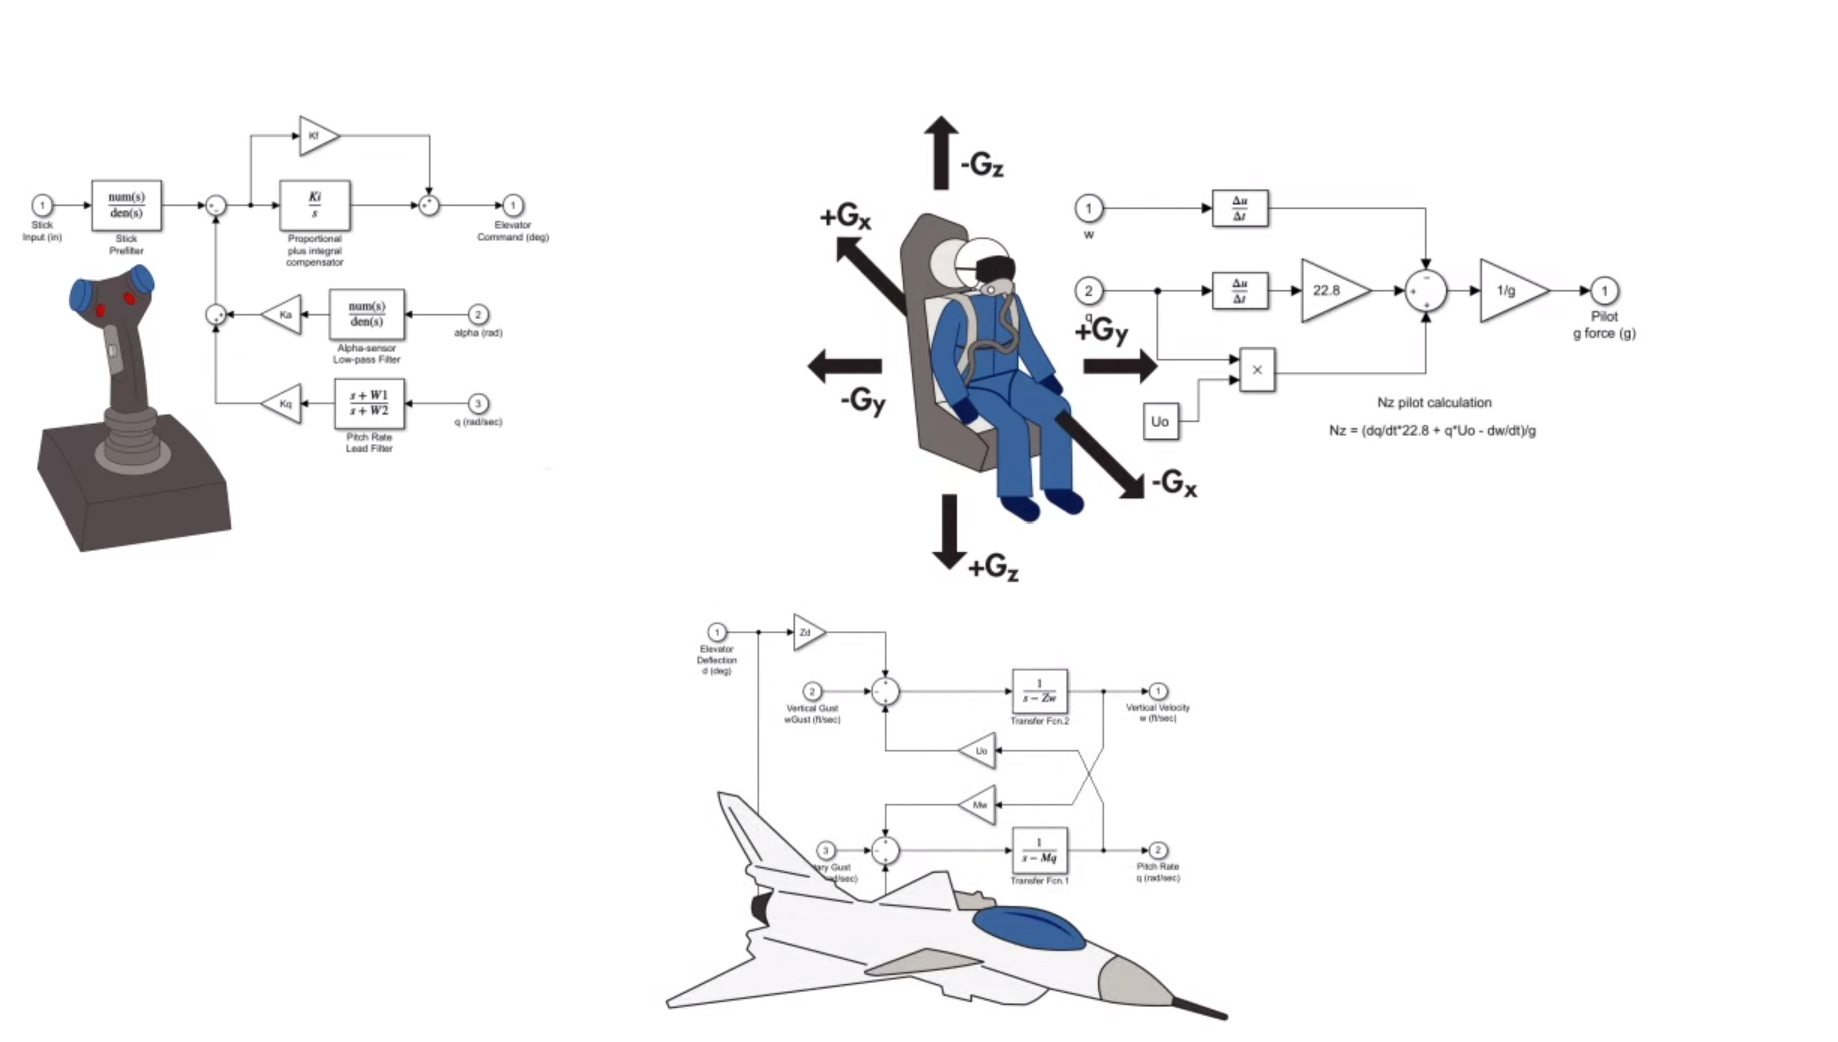

### How to ramp-up in Simulink?

Why Simulink? Simulink is today used in many applications fields (automotive, power electronics, electrifications, digital twins) by top-class companies (check these [user stories](https://www.mathworks.com/company/customer-stories/search.html?q=&page=1) or [technical articles](https://www.mathworks.com/company/technical-articles.html?q=&page=1)).

With Simulink (and MATLAB) you can have one integrated tool chain from the beginning of development to the end, have clear traceability of requirements, easy maintain the software because it is implemented as a model from which automatically generate code.

If you don't know Simulink, you can ramp-up according to the following plan:

- Online Training (2h) - [Simulink Onramp](https://www.mathworks.com/learn/tutorials/simulink-onramp.html)

- Video Series (<50min) - [Getting Started with Simulink](https://www.mathworks.com/videos/series/getting-started-with-simulink.html)

- Video (<12min) - [Getting Started with Simulink for Controls](https://www.mathworks.com/videos/getting-started-with-simulink-69027.html)

- Video (<13min) - [Getting Started with Simulink for Signal Processing](https://www.mathworks.com/videos/getting-started-with-simulink-for-signal-processing-1586429627003.html)

- [Webpage](https://www.mathworks.com/products/simulink.html)

## Simscape Basics

### Intro

[**Simscape**](https://www.mathworks.com/products/simscape.html#:~:text=Simscape%E2%84%A2%20enables%20you%20to,diagrams%20and%20other%20modeling%20paradigms.) enables you to rapidly create models of physical systems within the Simulink environment. With Simscape, you build physical component models based on physical connections that directly integrate with block diagrams and other modeling paradigms. You model systems such as electric motors, bridge rectifiers, hydraulic actuators, and refrigeration systems, by assembling fundamental components into a schematic. Simscape add-on products provide more complex components and analysis capabilities.

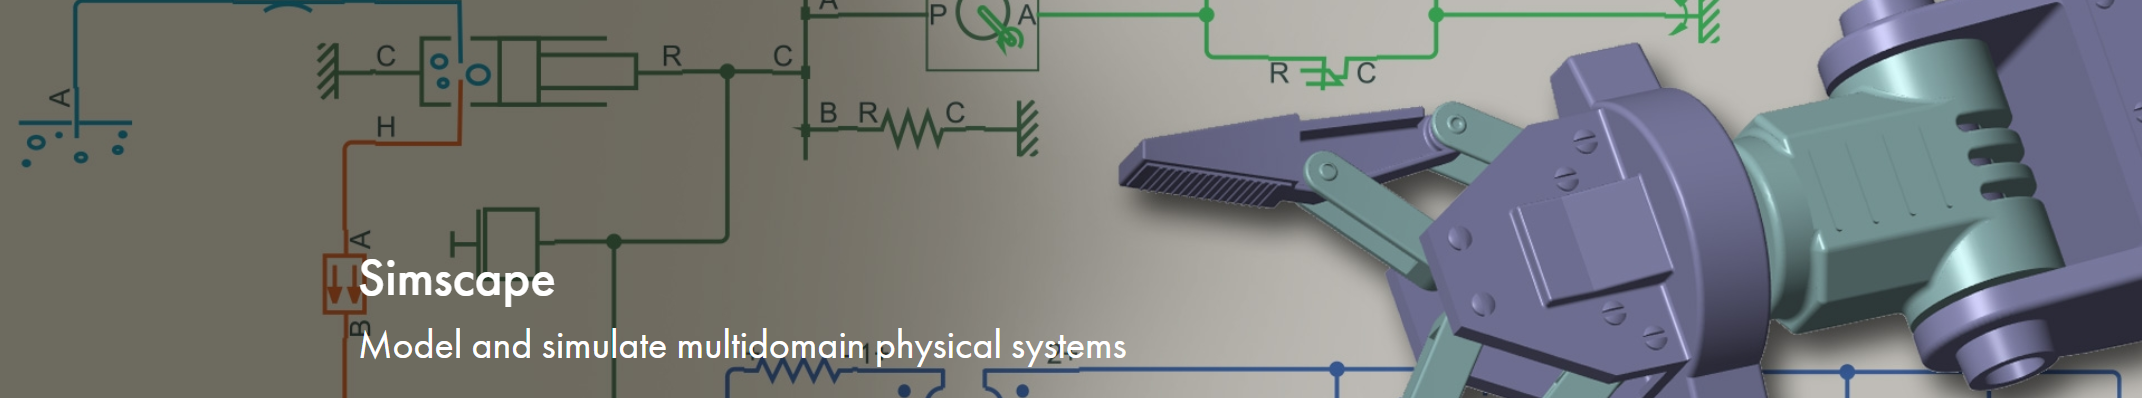

### Simscape and Simulink

While moving from Simulink to Simscape, you move the focus from the mathematical description (Simulink) of your systems towards the physical components (Simscape) which build up your system. The equations are intrinsically englobed within the physical Simscape components (someone else as written those equation for you, so you can focus on modeling!).

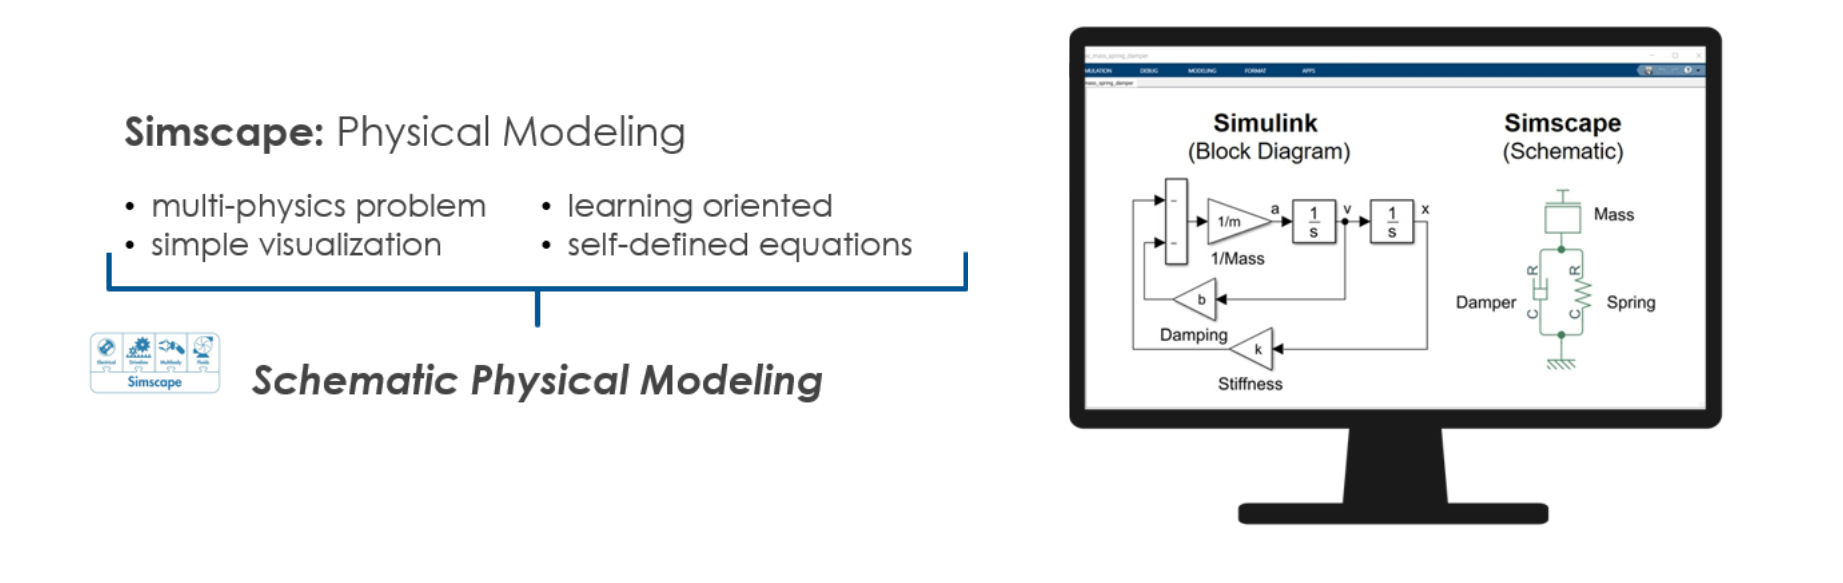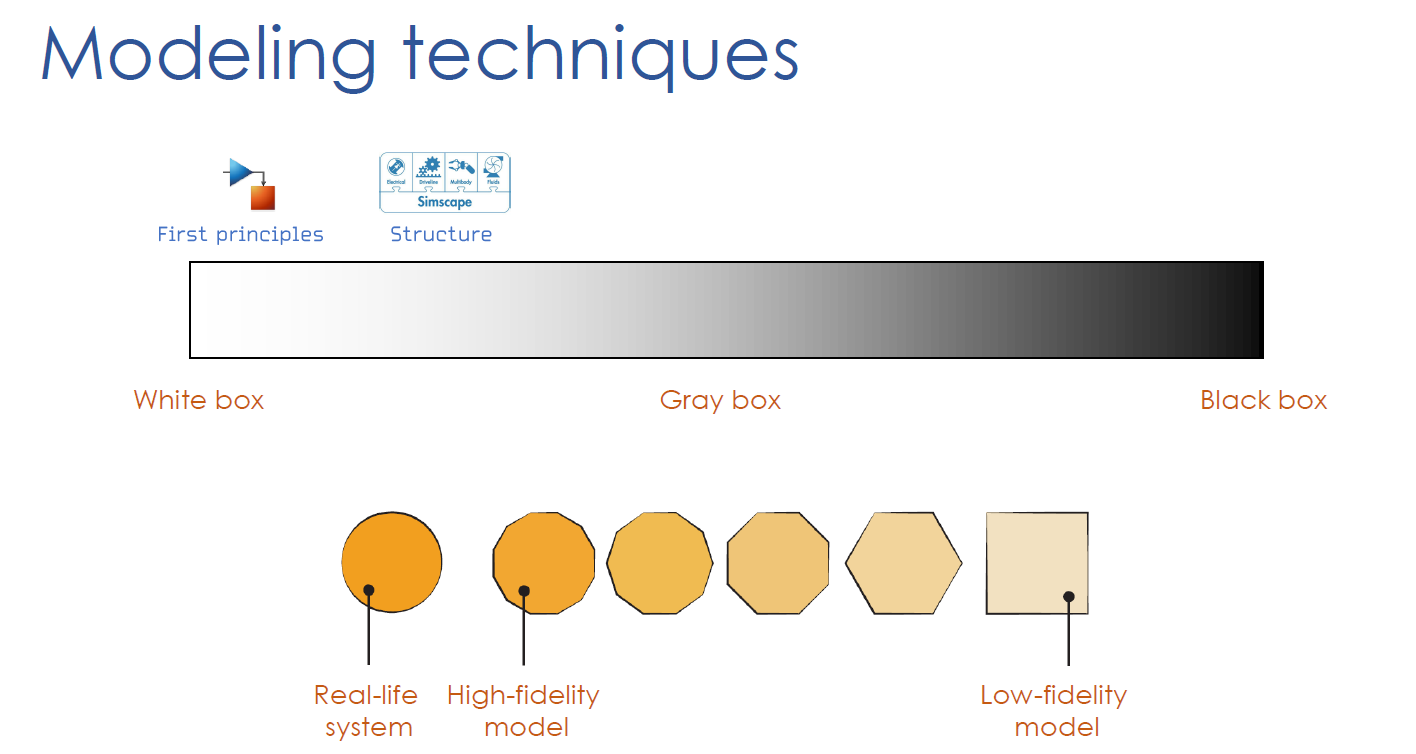

In Simscape modeling is based on the Physical Network approach: *each system is represented as consisting of functional elements that interact with each other by exchanging energy through their ports*. 

**Simulink**: model a problem by using the mathematical description (PDEs), signal-based input/output method

-  Arrows between blocks represent signals, direction is important

**Simscape**: model a problem by using the physical description (free body diagrams) -> physical network approach

- Line between blocks represent the flowing energy, direction is not important

The [basic principles of modeling physical networks](https://www.mathworks.com/help/physmod/simscape/ug/basic-principles-of-modeling-physical-networks.html#bq89sba-6) is based on (i) Through and Across variables and (ii) nondirectional physical connections.

Physical Network approach supports two types of variables:

- **Through** — Variables that are measured with a gauge connected in series to an element.

- **Across **— Variables that are measured with a gauge connected in parallel to an element.

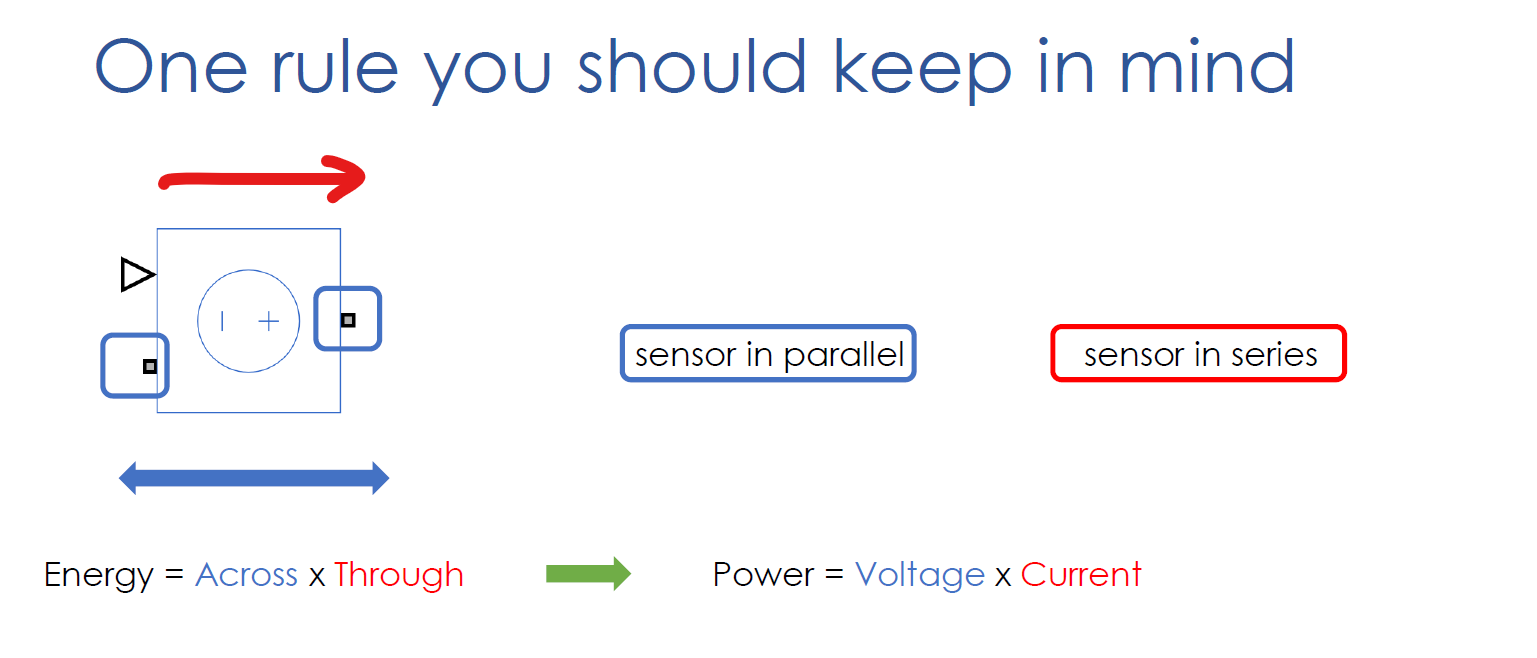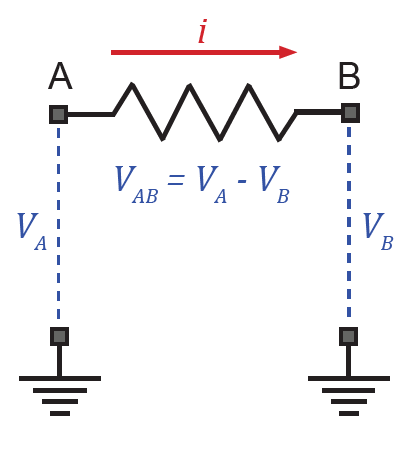

Simscape blocks may have the following types of ports:

- **Physical conserving ports** — Nondirectional ports (for example, hydraulic or mechanical) that represent physical connections and relate physical variables based on the Physical Network approach.

- **Physical signal ports **— Unidirectional ports transferring signals that use an internal Simscape engine for computations.

*The number of connection ports for each element is determined by the number of energy flows it exchanges with other elements in the system, and depends on the level of idealization. *

The Simscape libraries include foundation elements, such as resistors, springs, and valves, and more complex components such as electric drives, transmissions, and heat exchangers. Simscape libraries include models in more than 10 physical domains, such as mechanical, electrical, and two-phase fluids. You can select the domain that includes the physical effects required for your application.

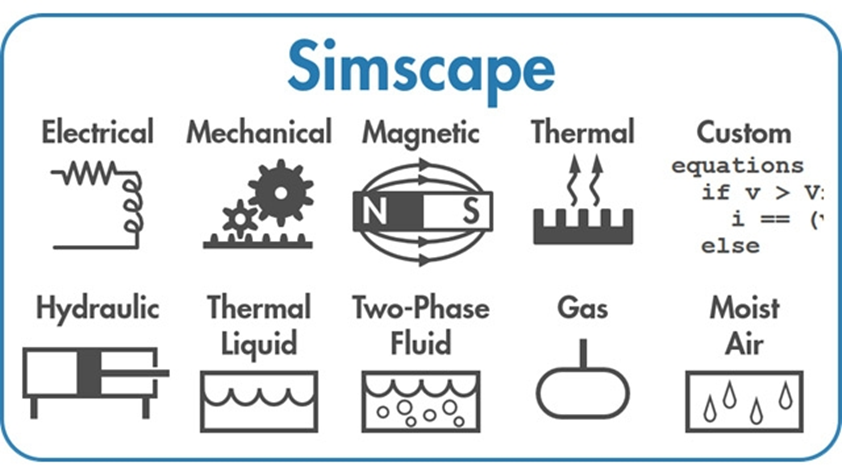

Simscape helps you develop control systems and test system-level performance. 

Moreover, you can create custom component models using the MATLAB-based Simscape language, which enables text-based authoring of physical modeling components, domains, and libraries. You can parameterize your models using MATLAB variables and expressions, and design control systems for your physical system in Simulink. To deploy your models to other simulation environments, including hardware-in-the-loop (HIL) systems, Simscape supports C-code generation.

### How to ramp-up in Simscape?

Why Simscape? As unique physical modelling tool Simscape is today used in many applications fields (automotive, power electronics, electrifications, digital twins) by top-class companies (check these [user stories](https://www.mathworks.com/company/user_stories/search.html?q=&fq[]=product:SS&page=1) or [technical articles](https://www.mathworks.com/company/newsletters/search.html?q=&fq[]=product:SS&page=1)).

If you don't know Simscape, you can ramp-up according to the following plan:

- Online Training (1.5h) - [Simscape Onramp](https://www.mathworks.com/learn/tutorials/simscape-onramp.html)

- Video (<10min) - [Getting Started with Simscape](https://www.mathworks.com/videos/getting-started-with-simscape-1612443969016.html)

- [Webpage](https://www.mathworks.com/products/simscape.html#:~:text=Simscape%E2%84%A2%20enables%20you%20to,diagrams%20and%20other%20modeling%20paradigms.)

## Simulation 1: Connecting blocks, input, output, time vector

PARAMETERS

t_s = 10;
h   = 0.01;

Sin Input

A=1;
f=1;

SIMULATION AND PLOTS

sim sin_w_st
% plots
figure;
plot(t,y);
xlabel('t(s)'); ylabel('sin (rad.)'); title('simula sin'); 

## Simulation 2: Transfer function

clc;clear all;close all

PARAMETERS

t_s = 10;
h   = 0.01;
step=1;
A=1;
B=1;

SIMULATION AND PLOTS

sim tf_function
figure;
plot(t,r,'r',t,y,'b');
xlabel('Time (s)'); ylabel('Input-Output '); title('Transfer function'); 

## Simulation 3: On-Off Control for a liquid tank

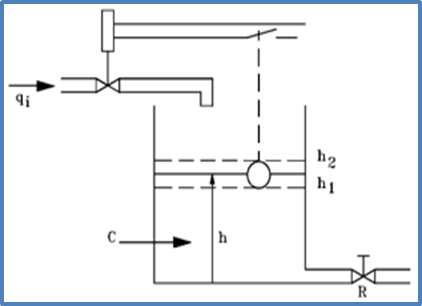

clc;clear all;close all

PARAMETERS

t_s = 10;
h   = 0.01;
A=1;
B=1;
Step=1;

SIMULATION AND PLOTS

sim on_off
figure;
plot(t,r,'r',t,y,'b');
xlabel('t(s)'); ylabel('input-output '); title('transfer function');


## Simulation 4: Inertia wheel

PARAMETERS

t_s = 6;
h   = 0.001;
K=1;
J=1;


SIMULATION AND PLOTS

sim inertia
figure;
plot(t,y);
xlabel('t(s)'); ylabel('angle (rad)'); title('Inertia+Coulomb friction'); 

## Simulation 5: Inertia wheel (MATLAB function)

PARAMETERS

t_s = 6;
h   = 0.001;
K=1;
J=1;

SIMULATION AND PLOTS

sim inertia2
figure;
plot(t,y);
xlabel('t(s)'); ylabel('angle (rad)'); title('Inertia+Coulomb friction'); 

## Simulation 6: DC Motor Simulation

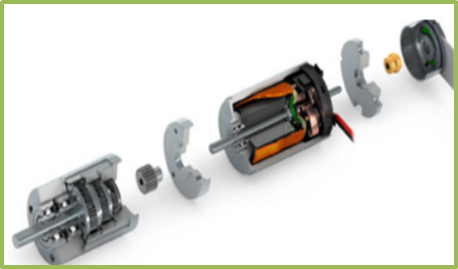

%%% System configuration
t_s=10;
h=0.001;
%Motor and simulation parameters
ref=1;
K1=0.00302;
J1=2.97E-07;
v1=8.23E-06;
A=K1/J1;
B=v1/J1;
%sat1=1.0;
%%% Simulation and plots
sim motor_sim;

Found algebraic loop containing: 
motor_sim/MOTOR/Saturation (discontinuity)
motor_sim/MOTOR/MATLAB Function
motor_sim/MOTOR/Sum (algebraic variable)
This algebraic loop may be resolved when the subsystem option 'Minimize algebraic loop occurrences' is selected on some or all of the atomic and enabled subsystems in this algebraic loop


figure;
plot(t,theta,'b',t,r,'r'); %motor position
xlabel('t(s)'); ylabel('Motor position  (rad)');title('DC Motor');

figure;
plot(t,omega,'b',t,r,'r'); %system response
xlabel('t(s)'); ylabel('Motor speed (rad/s)');title('DC Motor');

## Simulation 7: Mass-Spring-Damper,  Simulink and Simscape

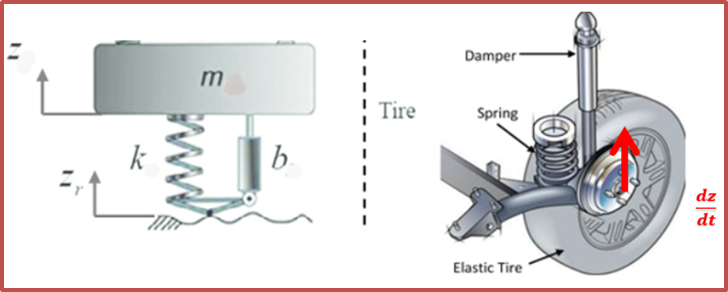

SIMULATION PARAMETERS

b=10;%N/(m/s)
k=400;% N/m
m=3.6;%kg
x0=0.25;%m
% 2. SIMULATION AND PLOTS
sim ssc_mass_spring_damper;
figure;
plot(v_sc,'g','LineWidth',2);
hold on
plot(v_sl,'--r','LineWidth',2);
xlabel('Time(s)'); ylabel('Velocity (m/s)'); title('Velocity of Mass');